# Use Features Extracted from AlexNet

net = alexnet;

imagePath = 'C:\Users\User\Google Drive\Greenstand\ANCombined';
 

 imds = imageDatastore(imagePath,'IncludeSubfolders',true,'LabelSource','foldernames');
 imds.Labels

[trainIm, testIm] = splitEachLabel(imds, 0.8,'randomized')
 
 trainData = augmentedImageDatastore([227 227], trainIm)
testData = augmentedImageDatastore([227 227], testIm)

trainFeatures = activations(net, trainData, 'fc7','OutputAs','rows')
testFeatures = activations(net, testData, 'fc7','OutputAs','rows')

classifier = fitcknn(trainFeatures, trainIm.Labels);

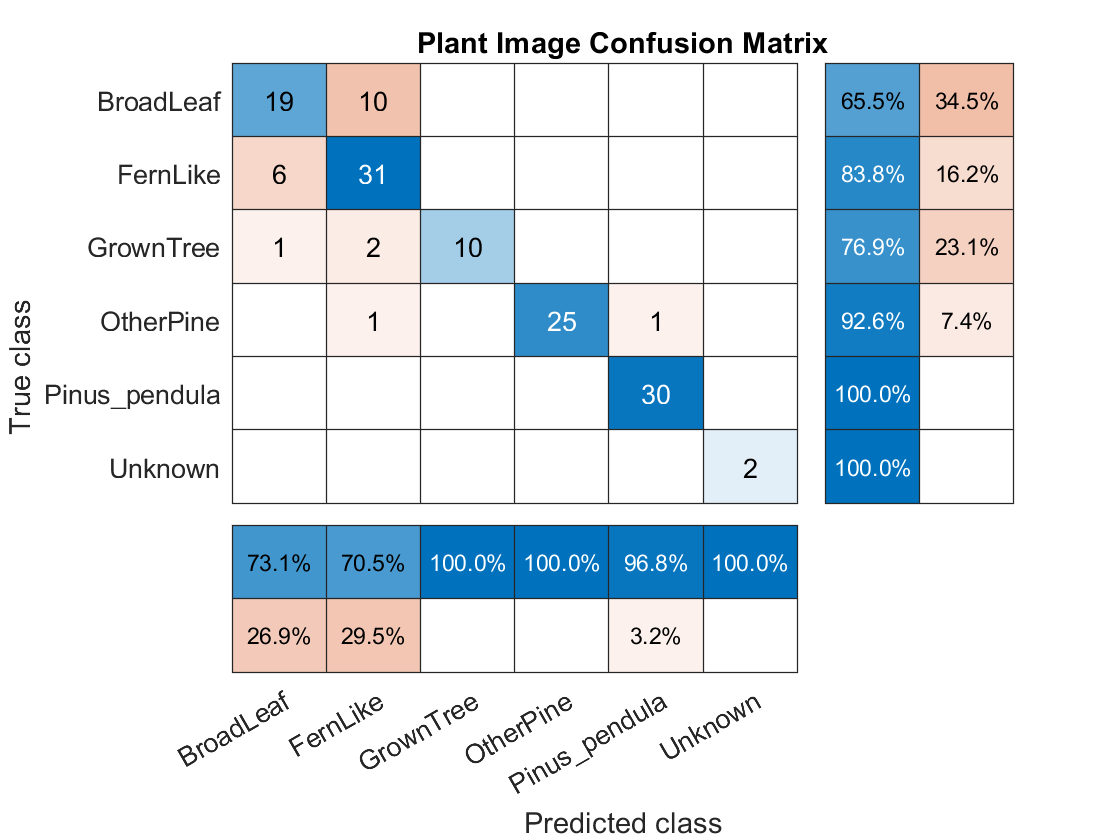

testPred = predict(classifier, testFeatures);
testAcc = nnz(testPred == testIm.Labels)/numel(testPred);

cc= confusionchart(testIm.Labels,testPred);

cc.ColumnSummary = 'column-normalized';
cc.RowSummary = 'row-normalized';
cc.Title = 'Plant Image Confusion Matrix';